# 源信号

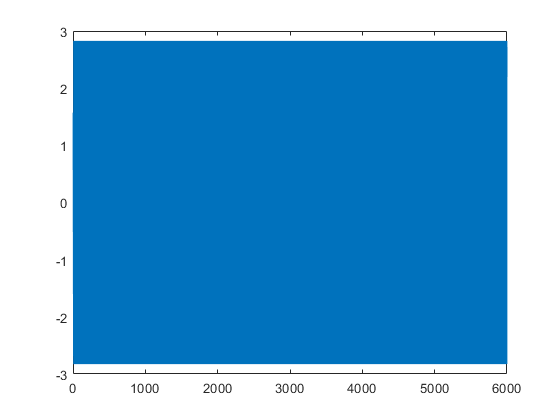


f_source = 100;
fs = f_source * 10;
A = 1;
E = 0 * A;
%采样点数 10s
N = 6 * fs;
n = 0 : N-1;
%时间序列
% global t;
t = n / fs ;

y_source_i = sin(2 * pi * f_source * t) + E;
y_source_q = cos(2 * pi * f_source * t) + E;
y_source = y_source_i + y_source_q * 1i;

y_an = angle(y_source);
figure;
plot(y_an);

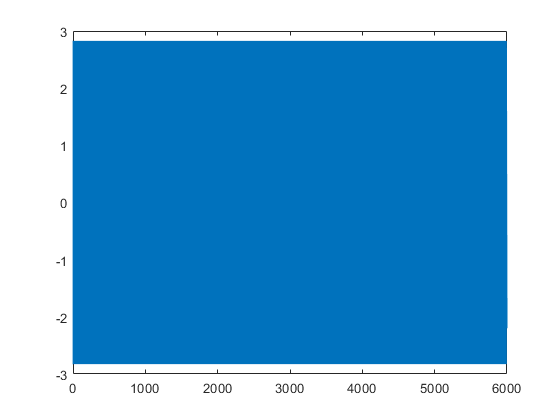


t_x = (n + 7) / fs ;
x_source_i = sin(2 * pi * f_source * t_x) + E;
x_source_q = cos(2 * pi * f_source * t_x) + E;
x_source = x_source_i + x_source_q * 1i;
x_an = angle(x_source);
figure;
plot(x_an);

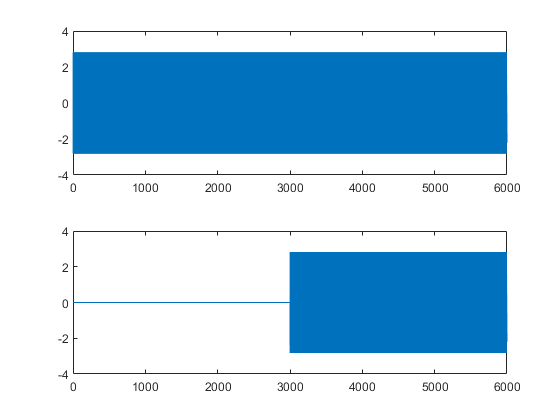


x_s = [zeros(1, length(x_source)/2) x_source(1, 1 + length(x_source)/2 : end) ];
x_s_an = angle(x_s);

figure
subplot(2,1,1);
plot(x_an);
subplot(2,1,2);
plot(x_s_an);

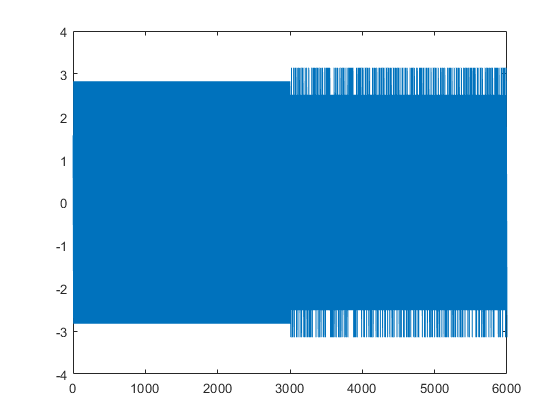


x_y = y_source + x_s;
xy_an = angle(x_y);

figure
plot(xy_an);